%% First Order Response
clc; clear variables;

s1 = load("lab3_order1_3.mat");

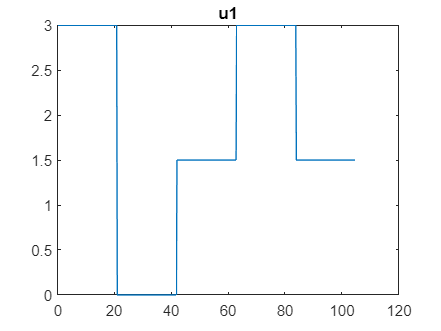


u = cell2struct(s1.data.InputData,"input_fields",1);
y = cell2struct(s1.data.OutputData,"output_fields",1);

plot(s1.t,u.input_fields); title(s1.data.InputName);

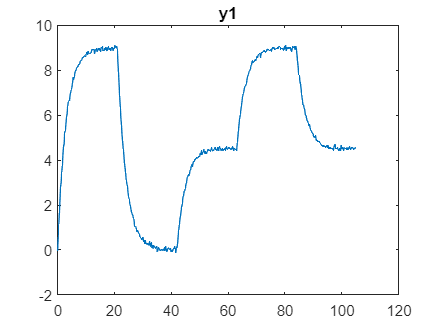

plot(s1.t,y.output_fields); title(s1.data.OutputName);


id = struct("u",u.input_fields(1:100),"y",y.output_fields(1:100),"t",s1.t(1:100));
val = struct("u",u.input_fields(201:500),"y",y.output_fields(201:500),"t",s1.t(201:500));

y_ss = 1/11*sum(id.y(90:100,:));
u_ss = 1/11*sum(id.u(90:100,:));
y0 = 0;
u0 = 0;

k = (y_ss-y0)/(u_ss-u0)

k = 2.9970

hs = tf(k,[63*y_ss/100 1])

hs =
 
     2.997
  -----------
  5.664 s + 1
 
Continuous-time transfer function.




y_id_cap = lsim(hs,id.u,id.t);
y_val_cap = lsim(hs,val.u,val.t);


mse_id = 1/100*(id.y)*sum((y_id_cap-id.y).^2);
mse_val = 1/300*(val.y)*sum((y_val_cap-val.y).^2);

figure,
subplot(2,1,1);
plot(id.t,id.y,id.t,y_id_cap); % title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(val.t,val.y,val.t,y_val_cap); % title("Validation MSE = " + string(mse_val))

%% Second Order Response
clear variables;

s2 = load("lab3_order2_3.mat");


u = cell2struct(s2.data.InputData,"input_fields",1);
y = cell2struct(s2.data.OutputData,"output_fields",1);

"plot"

ans = "plot"

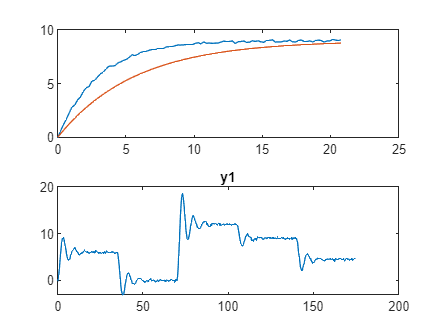

plot(s2.t,u.input_fields); title(s2.data.InputName);
plot(s2.t,y.output_fields); title(s2.data.OutputName);


id = struct("u",u.input_fields(1:100),"y",y.output_fields(1:100),"t",s2.t(1:100));
val = struct("u",u.input_fields(201:500),"y",y.output_fields(201:500),"t",s2.t(201:500));

y_ss = 1/11*sum(id.y(90:100,:));
u_ss = 1/11*sum(id.u(90:100,:));
y0 = 0;
u0 = 0;

k = (y_ss-y0)/(u_ss-u0) % gain

k = 2.9789

M = (id.t(1)-y_ss)/(y_ss-y0)

M = -1

zeta = log(1/M)/sqrt(pi^2+log(M)^2) % damping factor

zeta = 0.0000e+00 + Infi

wn = 2*pi/(id.t(3)-id.t(1))/sqrt(1-zeta^2) % natural frequency

wn = 0

hs = tf(k*wn^2,[1 2*zeta*wn wn^2])

hs =
 
  NaN
 
Static gain.




y_id_cap = lsim(hs,id.u,id.t);
y_val_cap = lsim(hs,val.u,val.t);

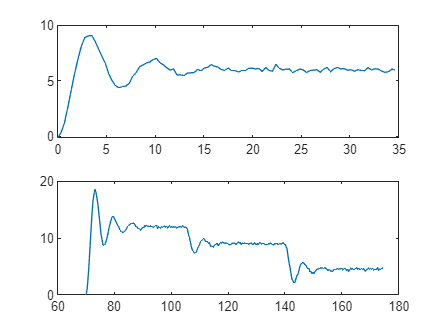


mse_id = 1/100*(id.y)*sum((y_id_cap-id.y).^2);
mse_val = 1/300*(val.y)*sum((y_val_cap-val.y).^2);

figure,
subplot(2,1,1);
plot(id.t,id.y,id.t,y_id_cap); % title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(val.t,val.y,val.t,y_val_cap); % title("Validation MSE = " + string(mse_val))